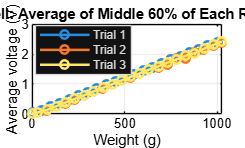

clear;
clc;
close all;

% ตัดข้อมูลด้านหน้าและด้านท้ายข้างละ 20%
trimFraction = 0.20;

dataFolder = 'C:\Users\Admin\Desktop\RMX\Lab\Load cell';
dataFile = fullfile(dataFolder, 'data3.mat');
% ...
S = load(dataFile);

variableNames = fieldnames(S);
weight_g = [];
averageVoltage_V = [];
trial = [];
sourceName = strings(0, 1);

for i = 1:numel(variableNames)
    name = variableNames{i};
    token = regexp(name, '^W(\d+)_(\d+)$', 'tokens', 'once');

    if isempty(token)
        continue;
    end

    trialNumber = str2double(token{2});
    loadNumber = str2double(token{1});

    % รอบที่ 1 บันทึกชื่อเป็นจำนวนเต็ม เช่น W0050_1 = 50 g
    % รอบที่ 2 และ 3 บันทึกทศนิยมหนึ่งตำแหน่ง เช่น W00305_2 = 30.5 g
    if trialNumber == 1
        currentWeight = loadNumber;
    else
        currentWeight = loadNumber / 10;
    end

    dataset = S.(name);
    voltageSignal = dataset.getElement(2).Values;
    voltage = squeeze(voltageSignal.Data);
    voltage = voltage(:);

    numberOfSamples = numel(voltage);
    firstSample = floor(trimFraction * numberOfSamples) + 1;
    lastSample = ceil((1 - trimFraction) * numberOfSamples);
    middleVoltage = voltage(firstSample:lastSample);

    weight_g(end + 1, 1) = currentWeight;
    averageVoltage_V(end + 1, 1) = mean(middleVoltage, 'omitnan');
    trial(end + 1, 1) = trialNumber;
    sourceName(end + 1, 1) = string(name);
end

result = table(weight_g, averageVoltage_V, trial, sourceName, ...
    'VariableNames', {'Weight_g', 'AverageVoltage_V', 'Trial', 'Source'});
result = sortrows(result, {'Trial', 'Weight_g'});

figure('Color', 'w');
hold on;

colors = lines(3);
for trialNumber = 1:3
    useRow = result.Trial == trialNumber;
    plot(result.Weight_g(useRow), result.AverageVoltage_V(useRow), ...
        '-o', ...
        'Color', colors(trialNumber, :), ...
        'LineWidth', 1.5, ...
        'MarkerSize', 5, ...
        'DisplayName', sprintf('Trial %d', trialNumber));
end

grid on;
box on;
xlabel('Weight (g)');
ylabel('Average voltage (V)');
title('Load Cell: Average of Middle 60% of Each Recording');
legend('Location', 'best');
ax = gca;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
ax.GridColor = [0.75 0.75 0.75];
ax.Title.Color = 'k';
hold off;

outputImage = fullfile(dataFolder, 'data3_average_middle.png');
outputTable = fullfile(dataFolder, 'data3_average_middle.csv');
exportgraphics(gcf, outputImage, 'Resolution', 200);

writetable(result, outputTable);

disp(result);

    Weight_g    AverageVoltage_V    Trial      Source  
    ________    ________________    _____    __________

          0         0.025767          1      "W0000_1" 
         50          0.11155          1      "W0050_1" 
        100          0.23051          1      "W0100_1" 
        150           0.3549          1      "W0150_1" 
        200          0.47995          1      "W0200_1" 
        250           0.6006          1      "W0250_1" 
        300          0.72086          1      "W0300_1" 
        350          0.84223          1      "W0350_1" 
        400           0.9632          1      "W0400_1" 
        450           1.0821          1      "W0450_1" 
        500           1.2042          1      "W0500_1" 
        550            1.322          1      "W0550_1" 
        600            1.436          1      "W0600_1" 
        650           1

fprintf('\nSaved graph: %s\n', outputImage);


Saved graph: C:\Users\Admin\Desktop\RMX\Lab\Load cell\data3_average_middle.png


fprintf('Saved averages: %s\n', outputTable);

Saved averages: C:\Users\Admin\Desktop\RMX\Lab\Load cell\data3_average_middle.csv
